# MATH 5603 Homework 1

## Bruce Campbell

### Problem 4

Solution of 1D Spring System $K \; x \; = f$ for $k_i =1$ , $n=20$ ,  and $f_i=0 \; \forall i \ne 5,16$, $f_5=1$ $f_{16} =-1$

K is a special type of a tridiagonal matrix called a Toeplitz matrix since the bands have the same value in each diagonal component. 

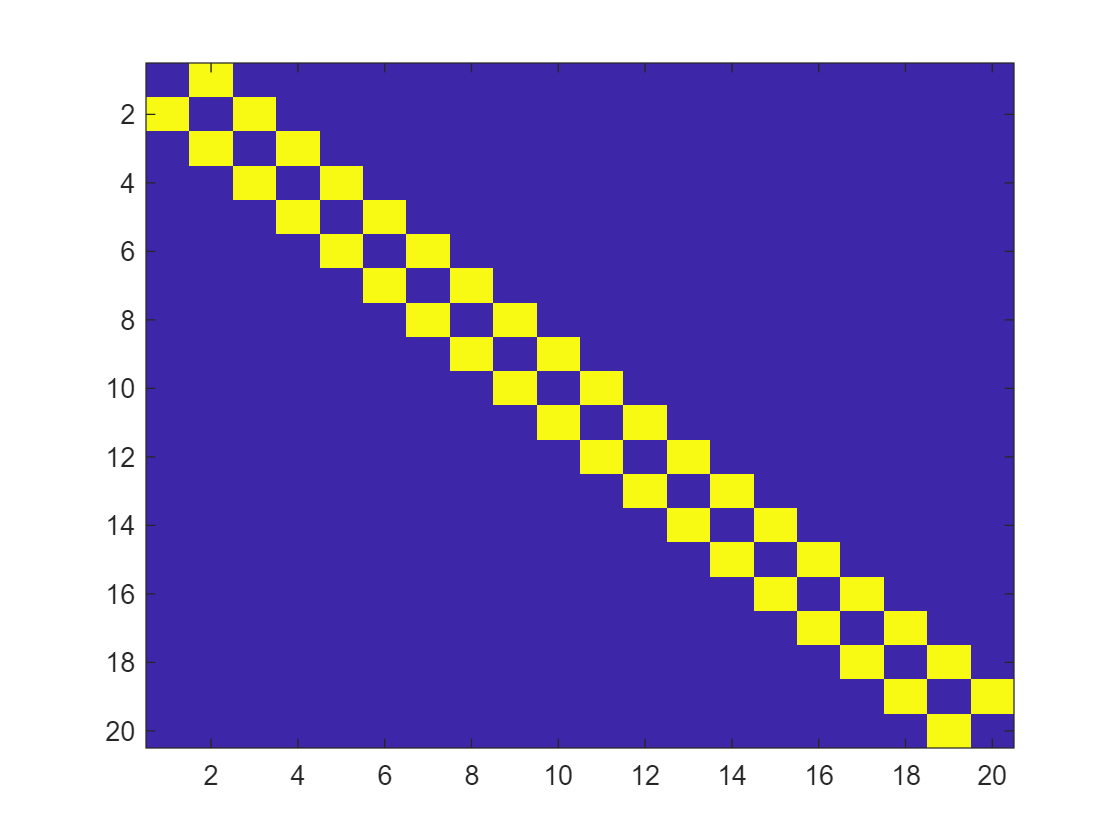

n=20;
r=zeros(n,1);
r(1)=0; % k_i -k_{i+1}=0
r(2)=1;
K=toeplitz(r);
f=zeros(n,1);
f(5)=1;
f(16)=-1;
image(K*256)

disp(f')

     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0    -1     0     0     0     0




x = K \ f;
disp(x')

     1     0    -1     0     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     0     1     0    -1




%Check result

sum(K*x -f)

ans =      0


% For fun I experimented with different f's to see what happened. In
% particular I set just one element in the middle to 1. I'm not sure the
% result lines up with my physical understanding of the system.  I'd expect
% the x's to be decreasing and all positive in the opposite direction of the force (I'm stretching them) 
% and negative and decreasing in absolute value in the direction of the
% force (I'm compressing them).
